# Lab 1 

A short lab concentrating on the meaing of 'sigma' and looking at some of the continuous and discrete analytic distributions we are likely to encounter.

## A little statistics

Converting a probability into a 'sigma'. 

This part of the lab is to figure out how, given a probability, to calculate the assoicated 'sigma' value. The sigma implicitly refers to the standard normal distribution. As we discussed in class, integrals of the standard normal distribution give probabilities.

1 - A and B

As we know Normal distributions are symmetrical, bell-shaped distributions that are useful in describing data. And Z-table is used to find the probability that a statistic is observed below, above, or between values on the standard normal distribution.

Here I try to integrating the standard normal distrobution with code normcdf() with several values of sigma, and they all match the z table.

 probability = normcdf([0,0.5,1,1.5,2,2.5,3]);
 disp(probability);

    0.5000    0.6915    0.8413    0.9332    0.9772    0.9938    0.9987



1 - C

Here I used several  probability values I found on the Z-table to get the associated vales of sigma 1,2,5 useing code norminv().   

sigma = norminv([0.84134,0.97725,2.86652*10^-7]);
disp(sigma);

    1.0000    2.0000   -5.0000



1 - D

The minus sign that appears because that a statistic is greater than Z, for large integer Z values.This equates to the area of the distribution above Z. All we have to do is to subtracting Z from 1. Like what i did below.

sigma1 = norminv(1-2.86652*10^-7);
disp(sigma1);

    5.0000



2 - A

Below I maked both the analytic pdf() and a realization with ~100k samples using a built-in Gamma distributions with a shape parameter as 9 and a scale parameter 0.5.

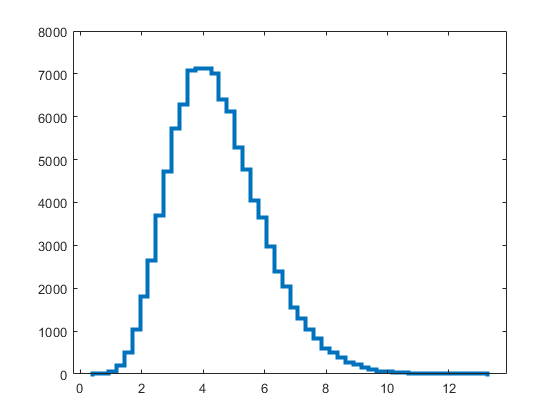

d = random('gamma', 9, 0.5, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)

2 - B

As you can see below the plot fit the histogram for gamma graph with a shape parameter as 9 and a scale parameter 0.5.

histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x = linspace(0,14);
pd = makedist("Gamma","a",9,"b",0.5);
plot(x,pdf(pd,x),"LineWidth",2);

3 - A, B, C, and D

The value I selected for my hypothetical measurment is 6 or above from the Gamma distribution with signal-free data. 

The statistical question I want to ask is" What is the probability and the sigma of the probability to find a value 8 or bigger on the gamma distributions with a shape parameter as 9 and a scale parameter 0.5 ?" 

As we know in order to find the total probability of value 6 or above we need use intergral. Intergrat from 8 to positive infinity of the Gamma equation with a shape parameter as 9 and a scale parameter 0.5.


$$\int_6^{+\infty } \textrm{Gamma}\left(x,9,0\ldotp 5\right)\;\textrm{dx}$$


Below I use code cdf() to do the math and find probability for 6 or above. 

probability1 = cdf(pd,6,'upper');
disp("probability for find 6 and above is " + probability1);

probability for find 6 and above is 0.15503


3 - E

Convert my probability into an equivalent sigma useing the code norminv().

sigma2 = norminv( 1-probability1);
disp("sigma for find 6 and above is " + sigma2);

sigma for find 6 and above is 1.0151


4

After I try various hypothetical measurement values and  see the probabilities and 'sigmas' change. I notes after the probability go below 50% the 'sigma' brcame negative. That also says if the value we try to find is on the right side of the mean the sigma is negative.  

x = 1:1:10;
probability2 = cdf(pd,x,'upper');
sigma3 = norminv( probability2);
disp(x);

     1     2     3     4     5     6     7     8     9    10



disp(probability2);

  Columns 1 through 8

    0.9998    0.9786    0.8472    0.5925    0.3328    0.1550    0.0621    0.0220

  Columns 9 through 10

    0.0071    0.0021



disp(sigma3);

  Columns 1 through 8

    3.4945    2.0264    1.0247    0.2341   -0.4321   -1.0151   -1.5377   -2.0143

  Columns 9 through 10

   -2.4544   -2.8647



## Non-continuous distributions

1 - A and B

A binomial experiment is a statistical experiment that has many properties. One, the experiment consists of *n* repeated trials. Second, each trial can result in just two possible outcomes. We call one of these outcomes a success and the other, a failure. Third, the probability of success, denoted by *P*, is the same on every trial.Forth, the trial are independent. 

Below code random() to generate many set of binomial with different probability and same number of trial. the code for binomial(N,P) take in two parameters. One is the number of trial 'N' and the other  is the probability of success 'P'.

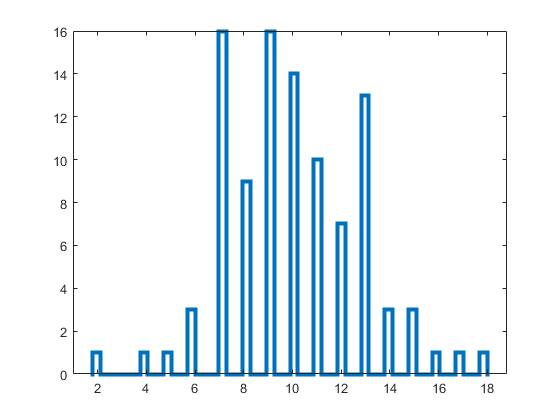

clc; close all; clear;
ntrial = 100;
prob1 = 0.1;
prob2 = 0.25;
prob3 = 0.5;
prob4 = 0.75;
prob5 = 0.9;
bino1 = random('Binomial',ntrial,prob1,[1,100]);
bino2 = random('Binomial',ntrial,prob2,[1,500]);
bino3 = random('Binomial',ntrial,prob3,[1,1000]);
bino4 = random('Binomial',ntrial,prob4,[1,5000]);
bino5 = random('Binomial',ntrial,prob5,[1,10000]);
histogram(bino1,50,'DisplayStyle',"stairs",'LineWidth',3)

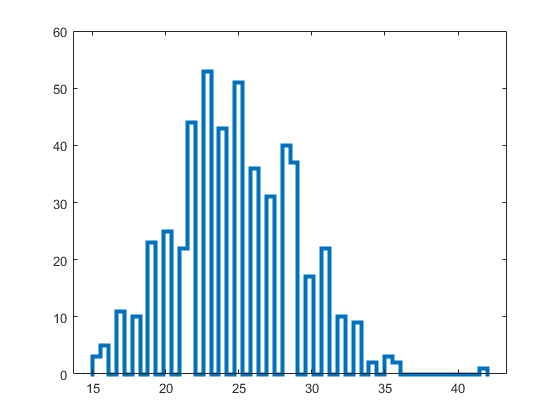

histogram(bino2,50,'DisplayStyle',"stairs",'LineWidth',3)

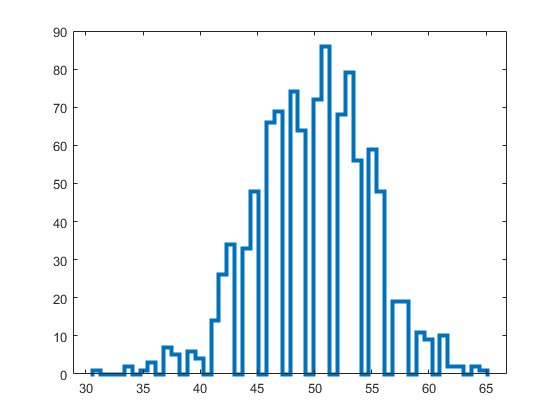

histogram(bino3,50,'DisplayStyle',"stairs",'LineWidth',3)

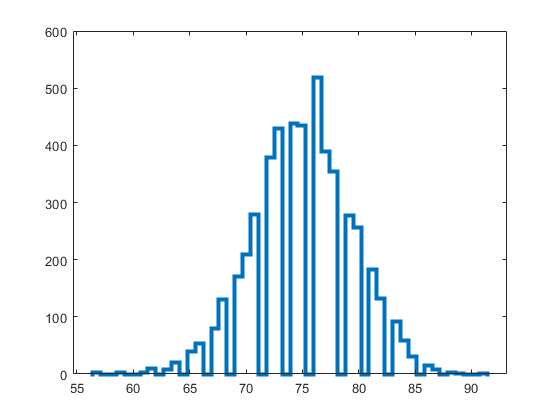

histogram(bino4,50,'DisplayStyle',"stairs",'LineWidth',3)

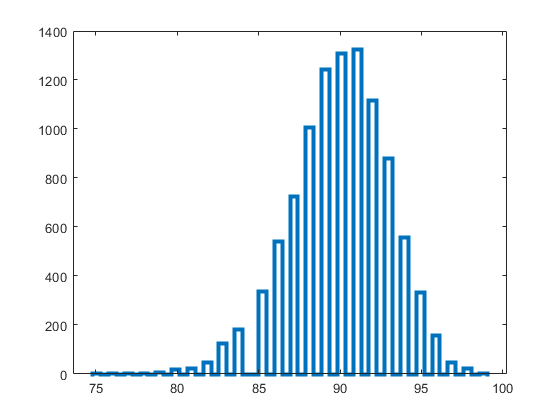

histogram(bino5,50,'DisplayStyle',"stairs",'LineWidth',3)

The graph above show that if more expriment was done the graph will be more bell like. The gap in the graph show that is not posible to get decimal number because all the possible out come for bonoimial is a whole number. All the mean from the graph is close to the probability we provide. 

1 - C 

The value I selected for my hypothetical measurment is 95 or above from the bonoimial distribution with signal-free data. 

The statistical question I want to ask is" What is the probability and sigma of the probability to find 95 success rate or above for the bonoimial distribution with 100  trials and 90 percent success rate ?" 

pd1 = makedist("Binomial",100,0.9);
probability3 = cdf(pd1,95,'upper');
disp("probability for find 95 success rate and above is " + probability3);

probability for find 95 success rate and above is 0.023711


sigma4 = norminv( 1-probability3);
disp("sigma for find 95 success rate and above is " + sigma4);

sigma for find 95 success rate and above is 1.9825


1 - D and E

With a discrete distribution, unlike with a continuous distribution, you can calculate the probability that X is exactly equal to some value. Since we use probability to calculate sigma so sigma will be discrete as well. 

The parameter of the distributions not discrete. Since parameter don't need to be discrete. for example the parameter for binimoal is posibility and number of trials. The number of trials has to be continuous whole number because you can't try seven time with out the six.